Call the ROC script

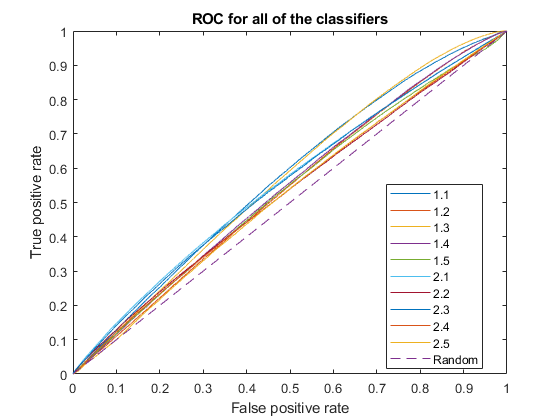

AUC11 = 0.5698

AUC12 = 0.5370

AUC13 = 0.5671

AUC14 = 0.5422

AUC15 = 0.5335

AUC21 = 0.5578

AUC22 = 0.5292

AUC23 = 0.5546

AUC24 = 0.5288

AUC25 = 0.5241

roc_v9_second_op

psame = 0.1360;
N = 6*31;
k = 0:N;

Idea : Choose classifier that has the greatest accuracy in our experiment

falsePosCell = {X11 X12 X13 X14 X15 X21 X22 X23 X24 X25};
truePosCell = {Y11 Y12 Y13 Y14 Y15 Y21 Y22 Y23 Y24 Y25};
thresholdCell = {T11 T12 T13 T14 T15 T21 T22 T23 T24 T25};
selectedPoints = zeros(length(falsePosCell),7); %th_distinguisher, th_bino, accuracy, fpr_bino, tpr_bino, fpr_dist, tpr_dist

%Get the best point for each one of them
for i = 1 : length(falsePosCell)
    fprVector = cell2mat(falsePosCell(i));
    tprVector = cell2mat(truePosCell(i));
    thresholdVector = cell2mat(thresholdCell(i));
    [selectedPoints(i,1), selectedPoints(i,2), selectedPoints(i,3), selectedPoints(i,4), selectedPoints(i,5), selectedPoints(i,6), selectedPoints(i,7)] = getThresholdDistinguisher(fprVector,tprVector,thresholdVector,psame,N);
end
clearvars falsePosCell truePosCell thresholdCell fprVector tprVector thresholdVector

Display thresholds for each classifier, their accuracy and total values for false positive rate and true positive rate

for i = 1 : size(selectedPoints,1)
    fprintf("Classifier %d",i);
    selectedPoints(i,1)
    selectedPoints(i,2)
    selectedPoints(i,3)
    selectedPoints(i,4)
    selectedPoints(i,5)
    selectedPoints(i,6)
    selectedPoints(i,7)
end

Classifier 1

ans = 0.9633

ans = 153

ans = 0.9198

ans = 0.0898

ans = 0.9198

ans = 0.7672

ans = 0.8582

Classifier 2

ans = 0.8660

ans = 173

ans = 0.8102

ans = 0.1925

ans = 0.8102

ans = 0.9037

ans = 0.9424

Classifier 3

ans = 0.9807

ans = 167

ans = 0.9443

ans = 0.0571

ans = 0.9443

ans = 0.8442

ans = 0.9269

Classifier 4

ans = 0.9439

ans = 163

ans = 0.8074

ans = 0.2039

ans = 0.8074

ans = 0.8453

ans = 0.8940

Classifier 5

ans = 0.9707

ans = 119

ans = 0.7446

ans = 0.2364

ans = 0.7446

ans = 0.6040

ans = 0.6578

Classifier 6

ans = 0.0264

ans = 74

ans = 0.8514

ans = 0.1475

ans = 0.8514

ans = 0.3466

ans = 0.4329

Classifier 7

ans = 0.0013

ans = 47

ans = 0.7166

ans = 0.2816

ans = 0.7166

ans = 0.2267

ans = 0.2687

Classifier 8

ans = 5.3756e-04

ans = 88

ans = 0.8313

ans = 0.1687

ans = 0.8313

ans = 0.4245

ans = 0.5056

Classifier 9

ans = 0.0011

ans = 59

ans = 0.6996

ans = 0.3068

ans = 0.6996

ans = 0.2923

ans = 0.3335

Classifier 10

ans = 1.4920e-06

ans = 105

ans = 0.6878

ans = 0.3023

ans = 0.6878

ans = 0.5372

ans = 0.5784

Which is the best classifier

[val,ind] = max(selectedPoints(:,3))

val = 0.9443

ind = 3

Plot binomial distributions for that classifier

ytrue = binopdf(k,N,selectedPoints(ind,7));
prandom = psame * selectedPoints(ind,7) + (1 - psame) * selectedPoints(ind,6)

prandom = 0.8555

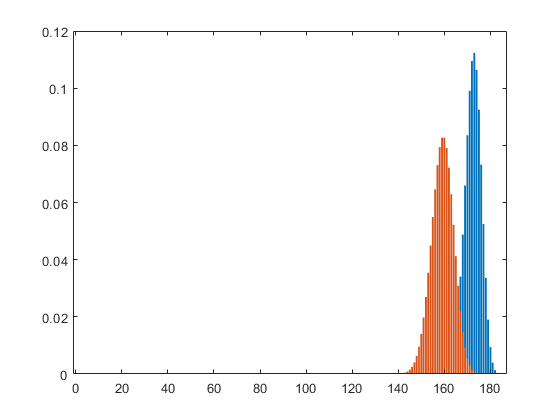

yrandom = binopdf(k,N,prandom);
bar(k,ytrue)
hold on
bar(k,yrandom)
hold off

Which gives us, according to Hanley's explanation

bitErrors = 521*(1-selectedPoints(ind,3))

bitErrors = 29.0130

cost = 0;
n2 = ceil(521/2);
for i = 1 : ceil(bitErrors/2)
    cost = cost + nchoosek(n2,i);
end

cost = cost * 521

cost = 5.0002e+26

Which is equivalent to 2^ to the 

exponent = log2(double(cost))

exponent = 88.6921

Save results

save('./results_characterization/v9_second_op.mat','selectedPoints');